# EDUCAT database visualization

clear
username = "analyst";
userInput = ' password: ';
password = input(userInput,'s');

import classes.measurement
import classes.instrument
import classes.data
m = measurement(username,password);

 
m.list

ans = 55×4 table
    id                  description                   start_time        end_time   
    __    _______________________________________    _____________    _____________

     1    'BLA BLA BLA [DELETE]'                                 0                0
     2    'Second dummy measurement [DELETE]'                    0                0
     6    'Thrid dummy measurment [DELETE]'                      0                0
     7    'test [DELETE]'                               2147483647       2147483647
     8    'test 2 [DELETE]'                          1570007771118    1570011375338
     9    'first start measurement test [DELETE]'       1571035739                0
    10    '1 [DELETE]'                               1571043406799                0
    11    '3 [DELETE]'                               1571047108485                0
    12

## Declaration of measurement

id= 58;
 
m=m.set_measurement_ID(id);
m = m.declaration();

## LOAD all current datasets

m = m.get_dataset_DB();
disp("done")

done


## Plot all measurement information

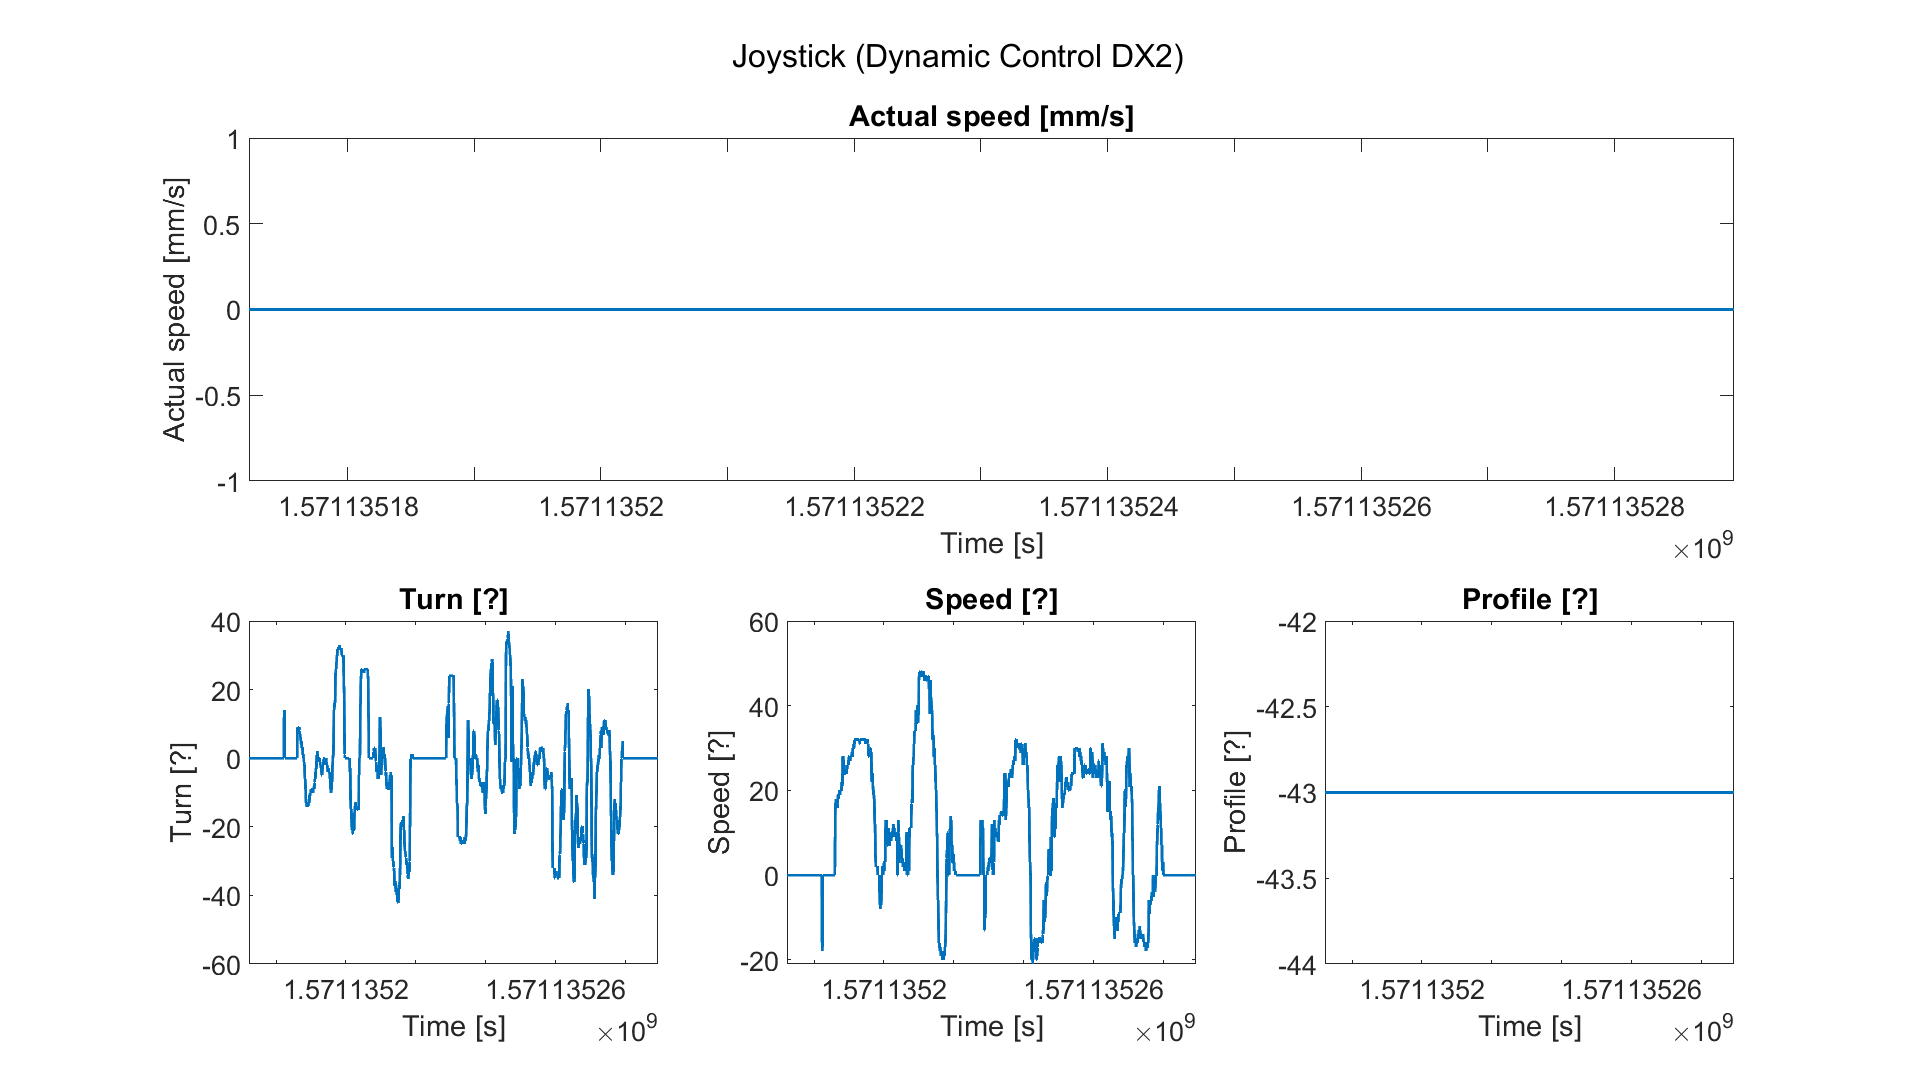

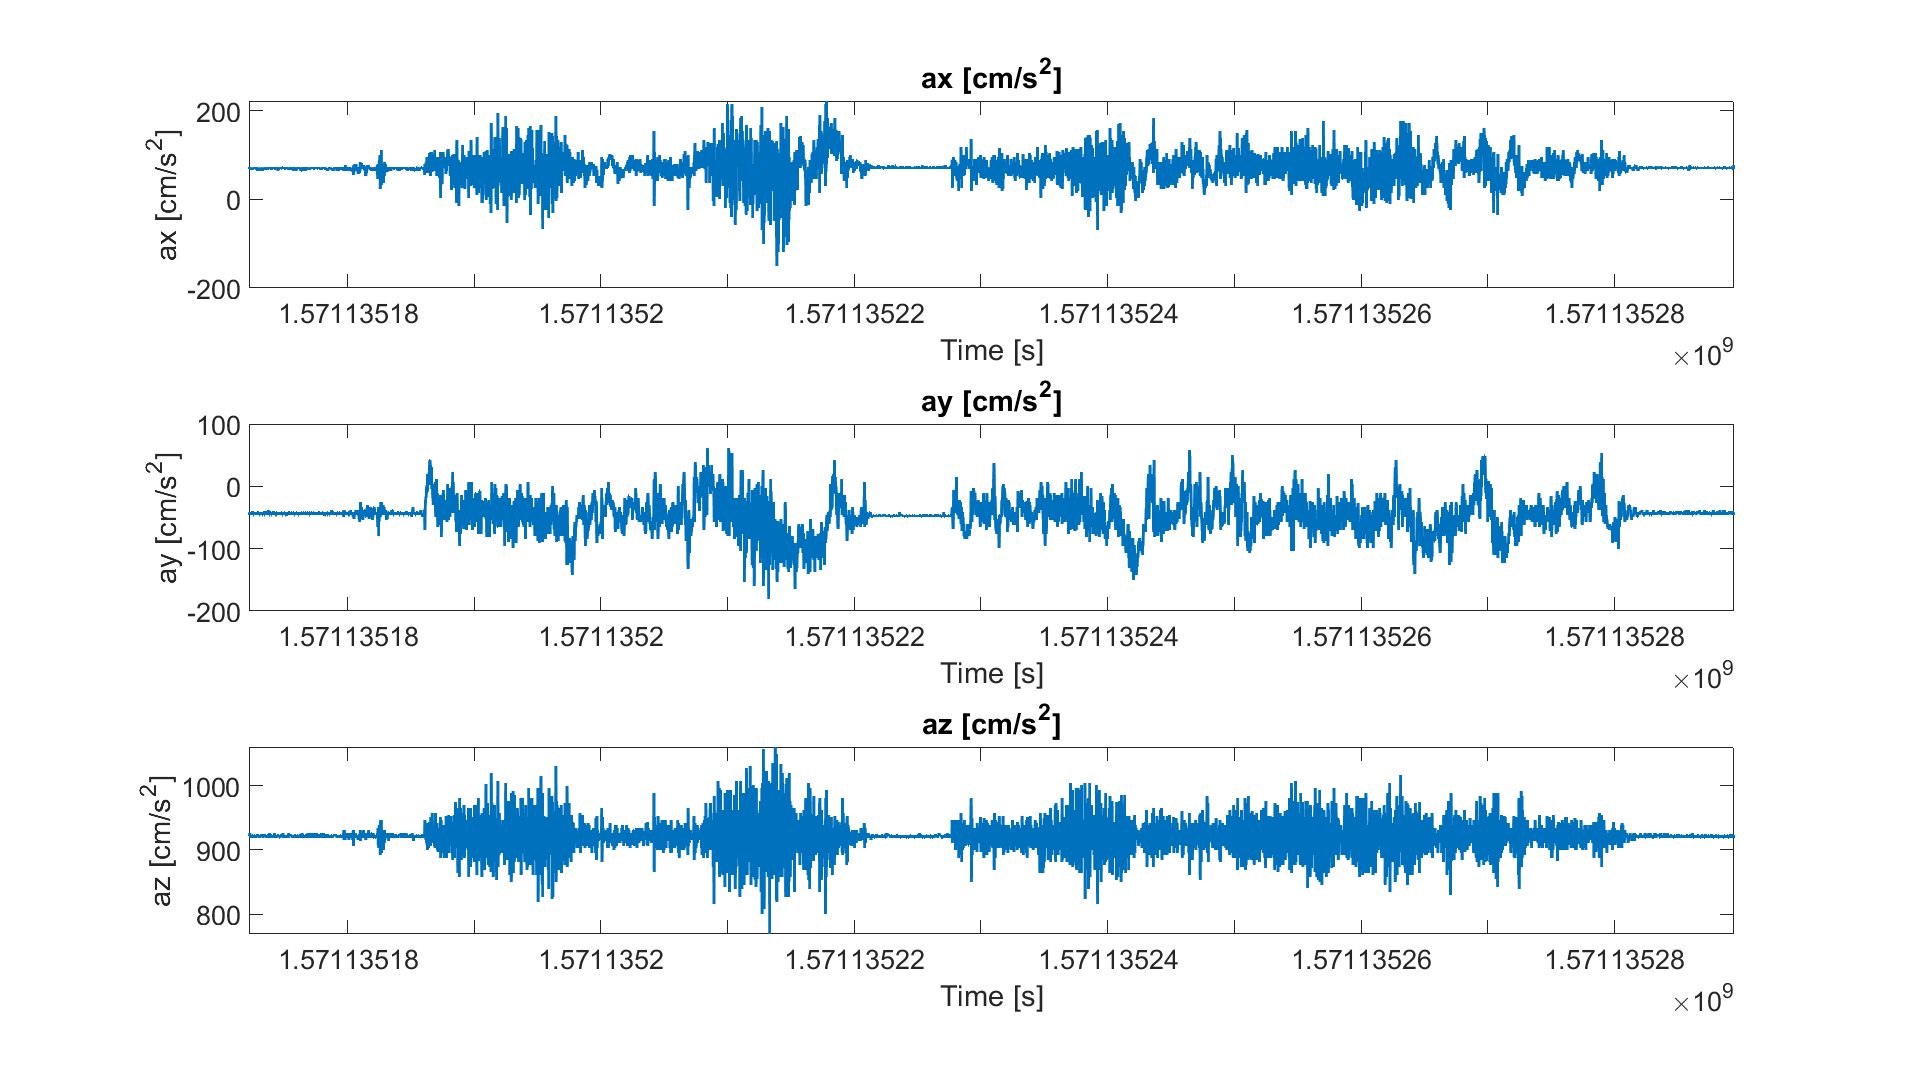

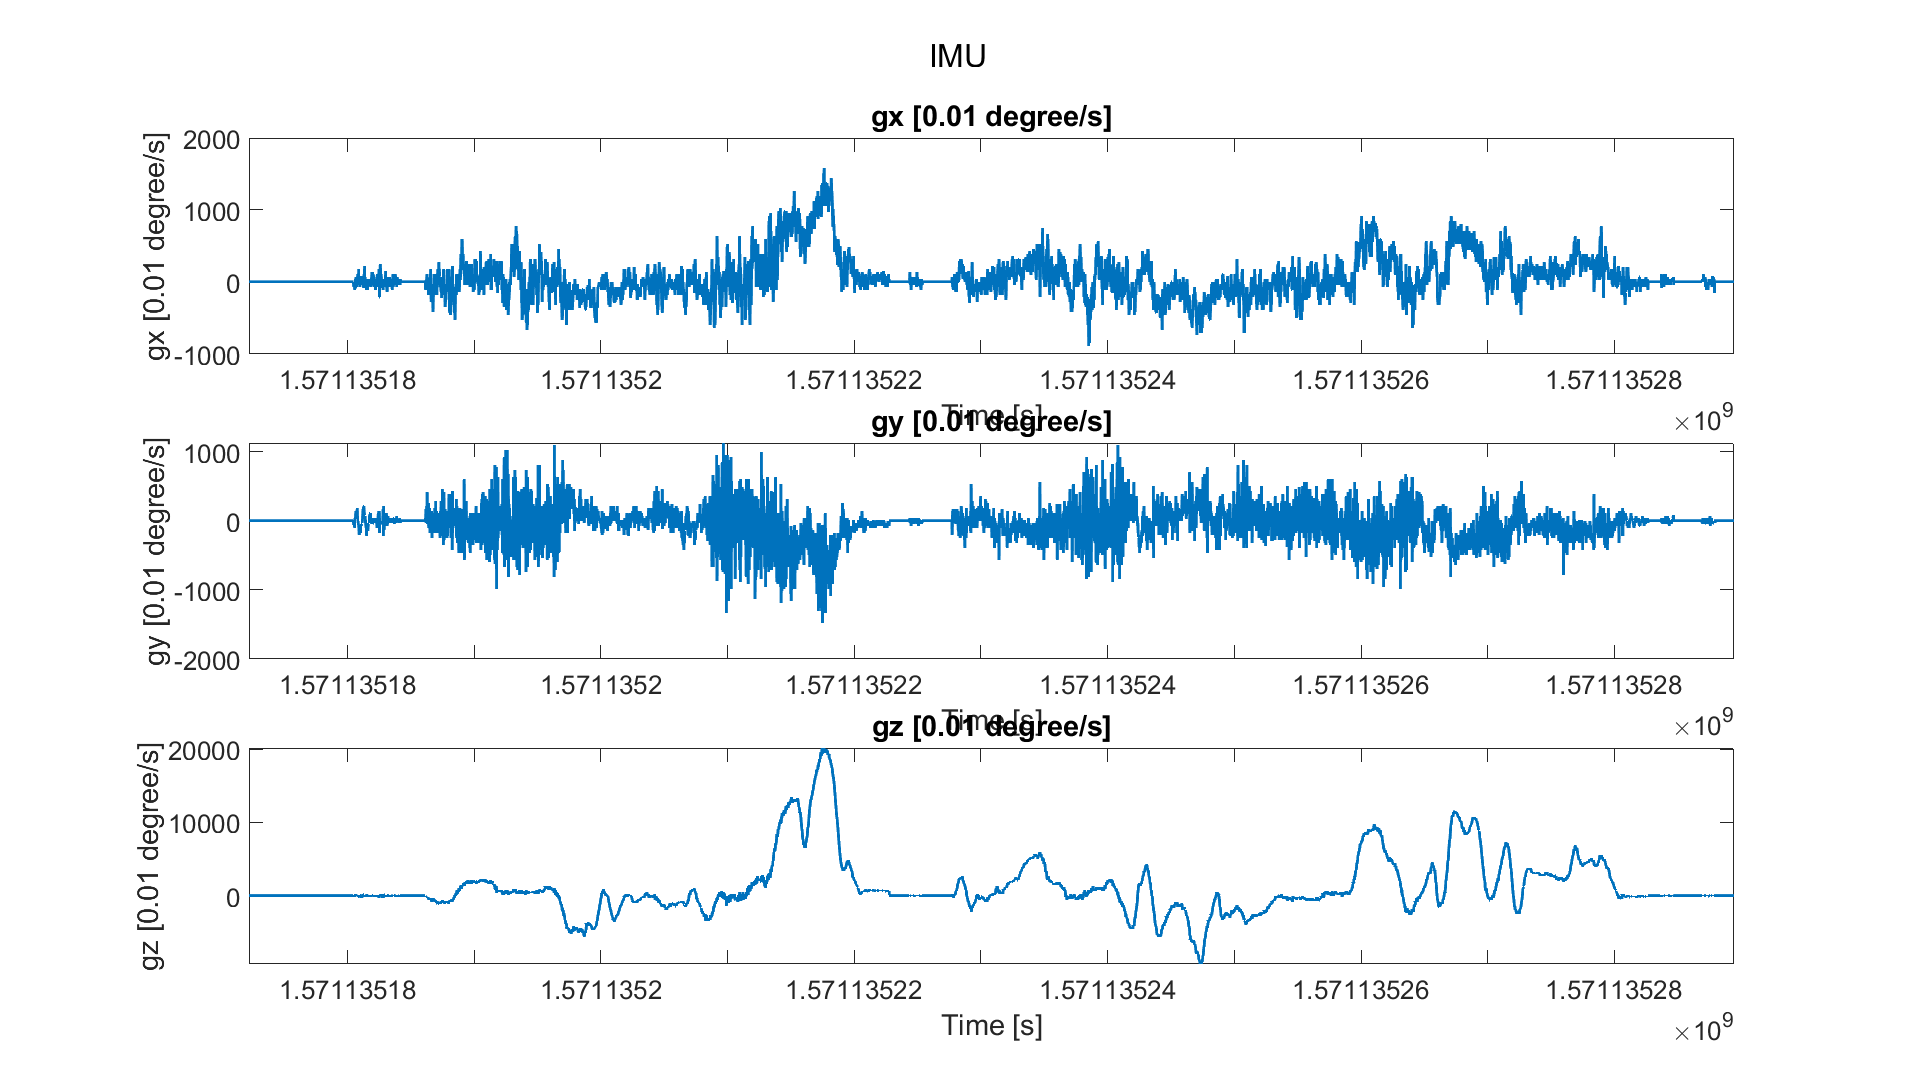

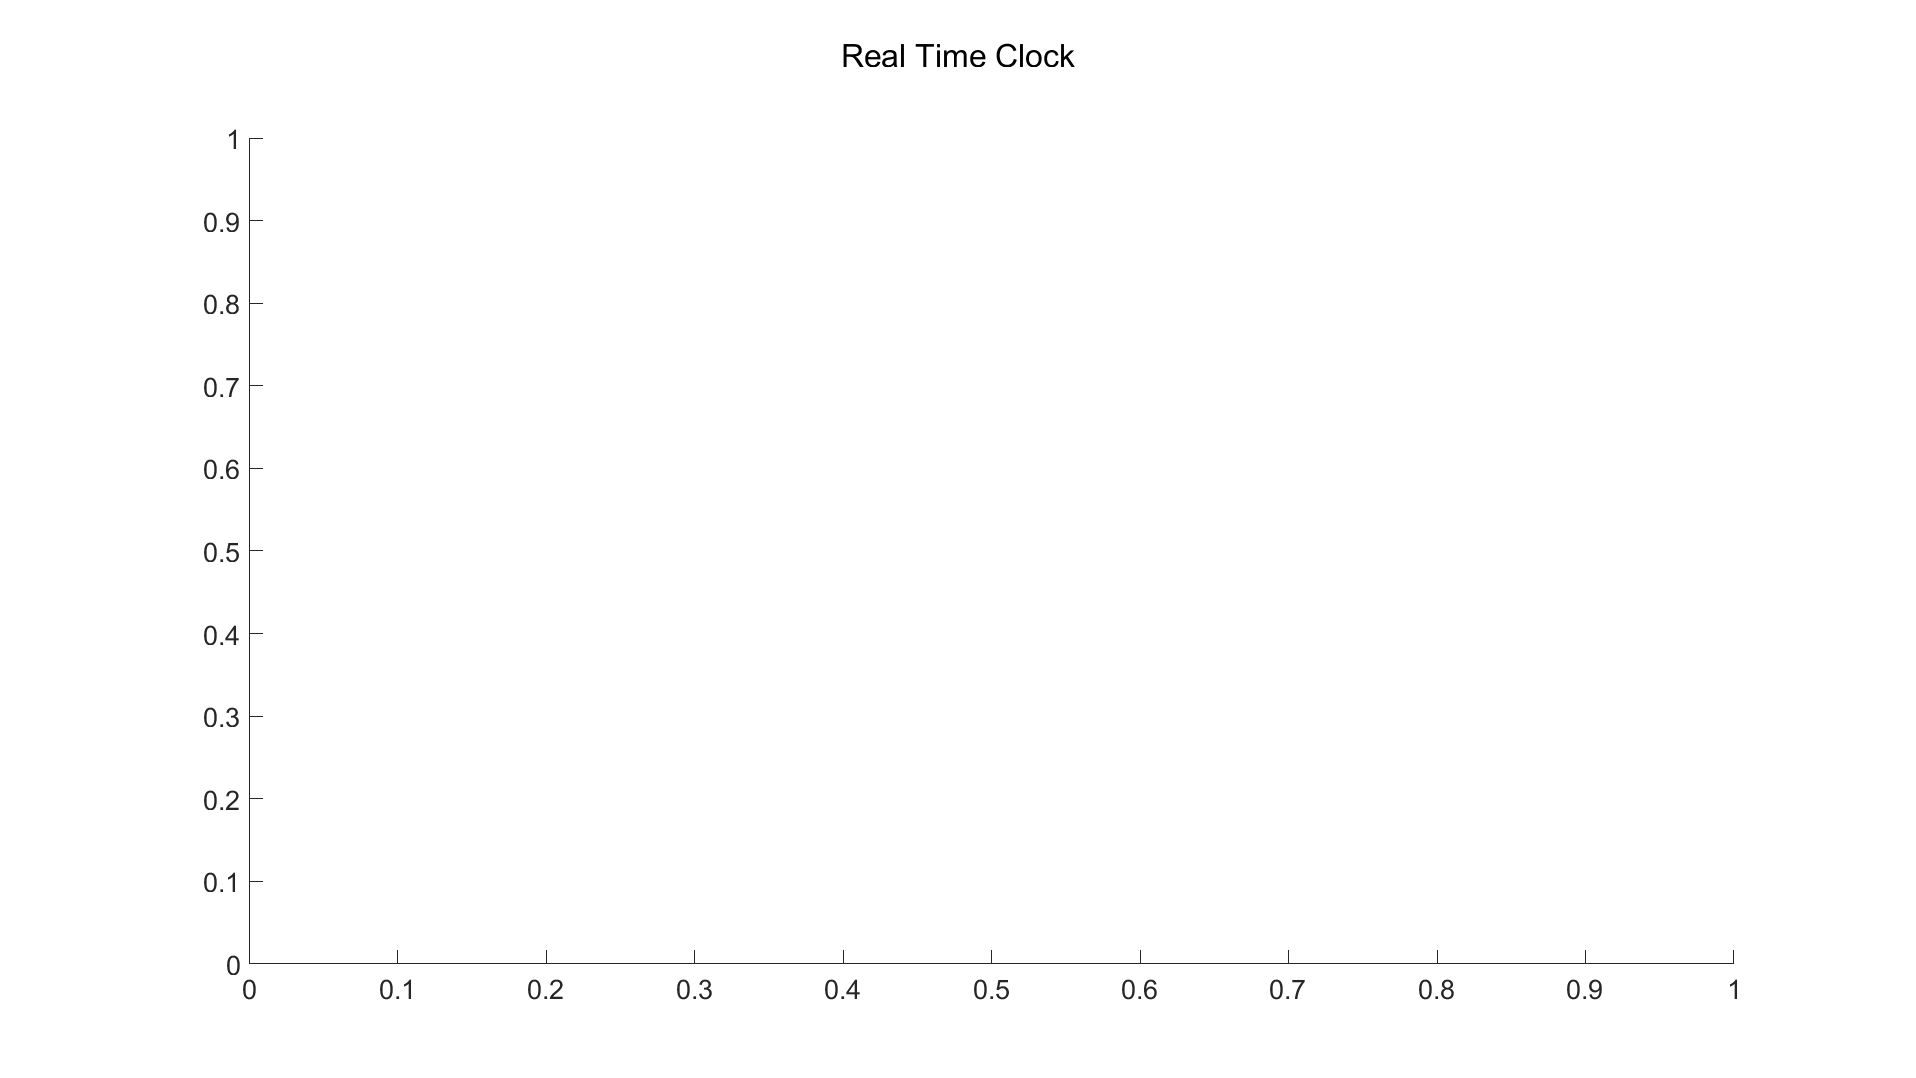

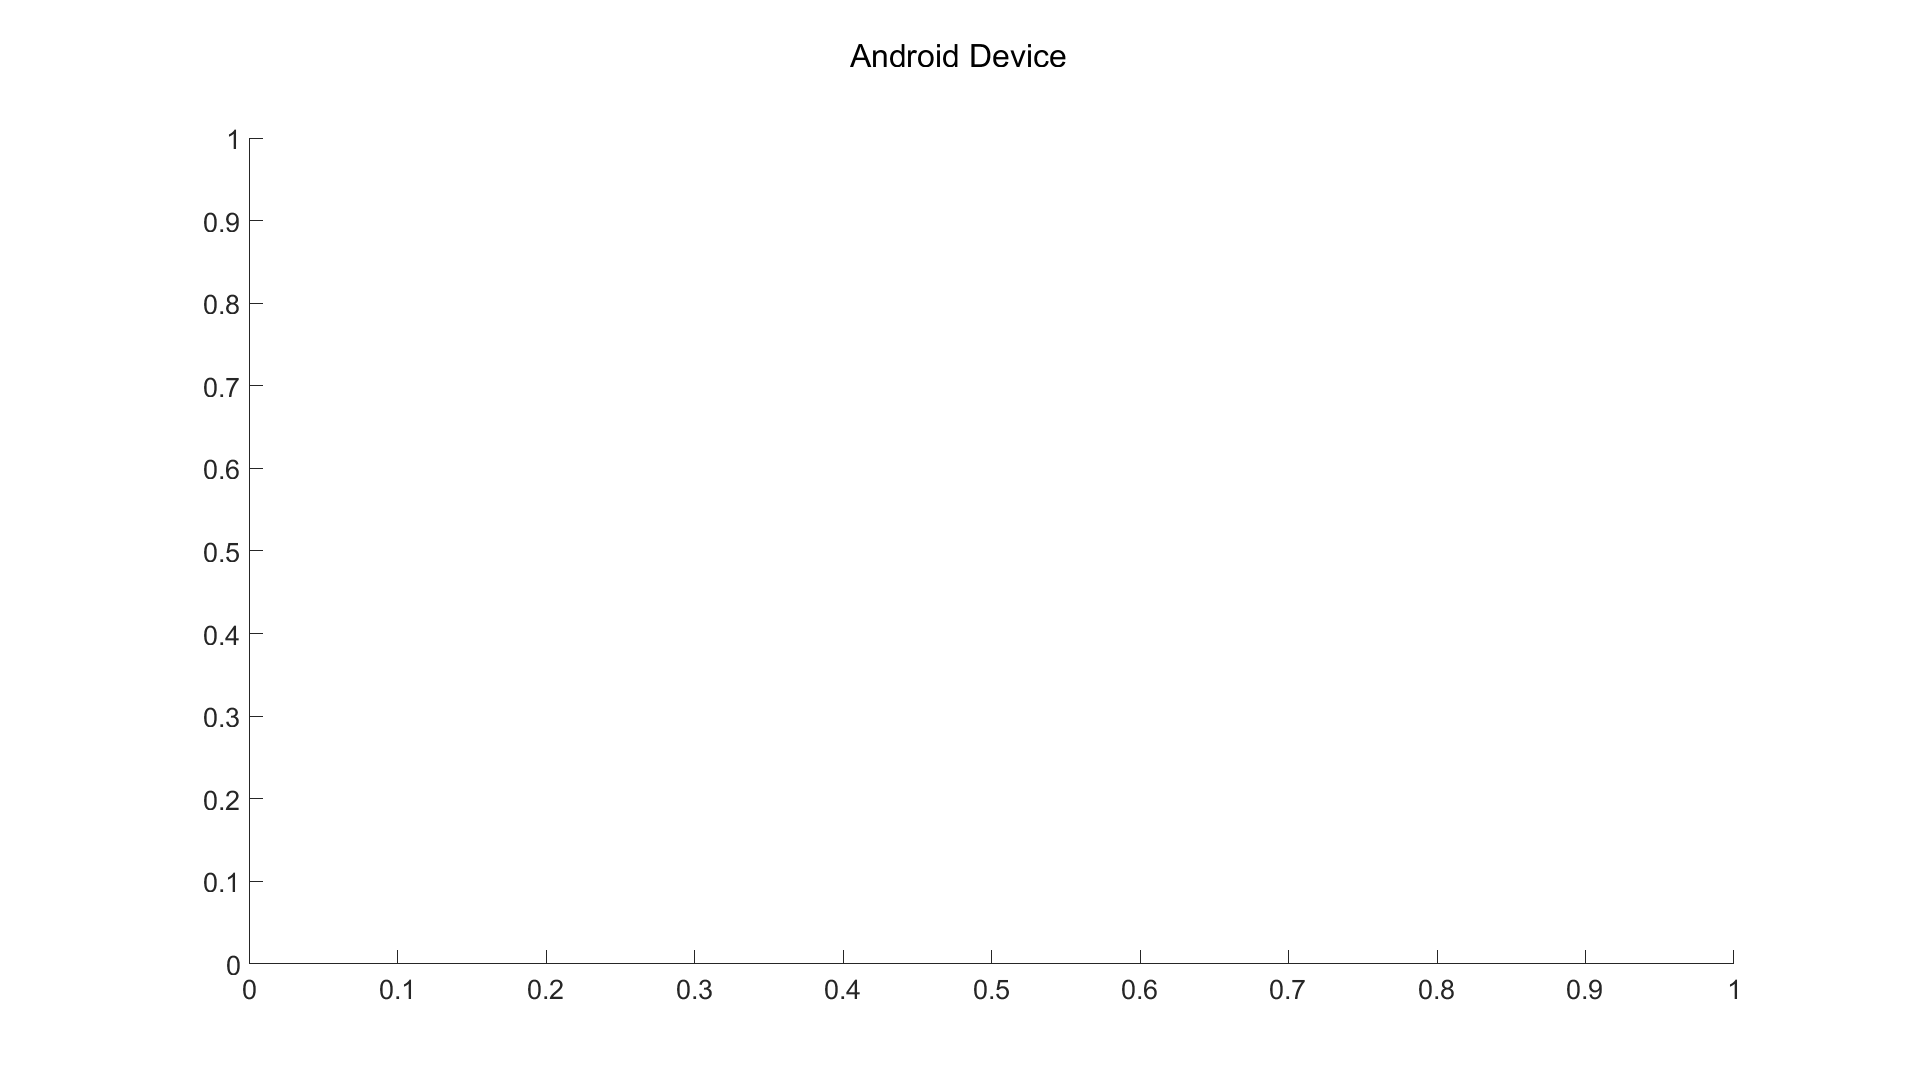

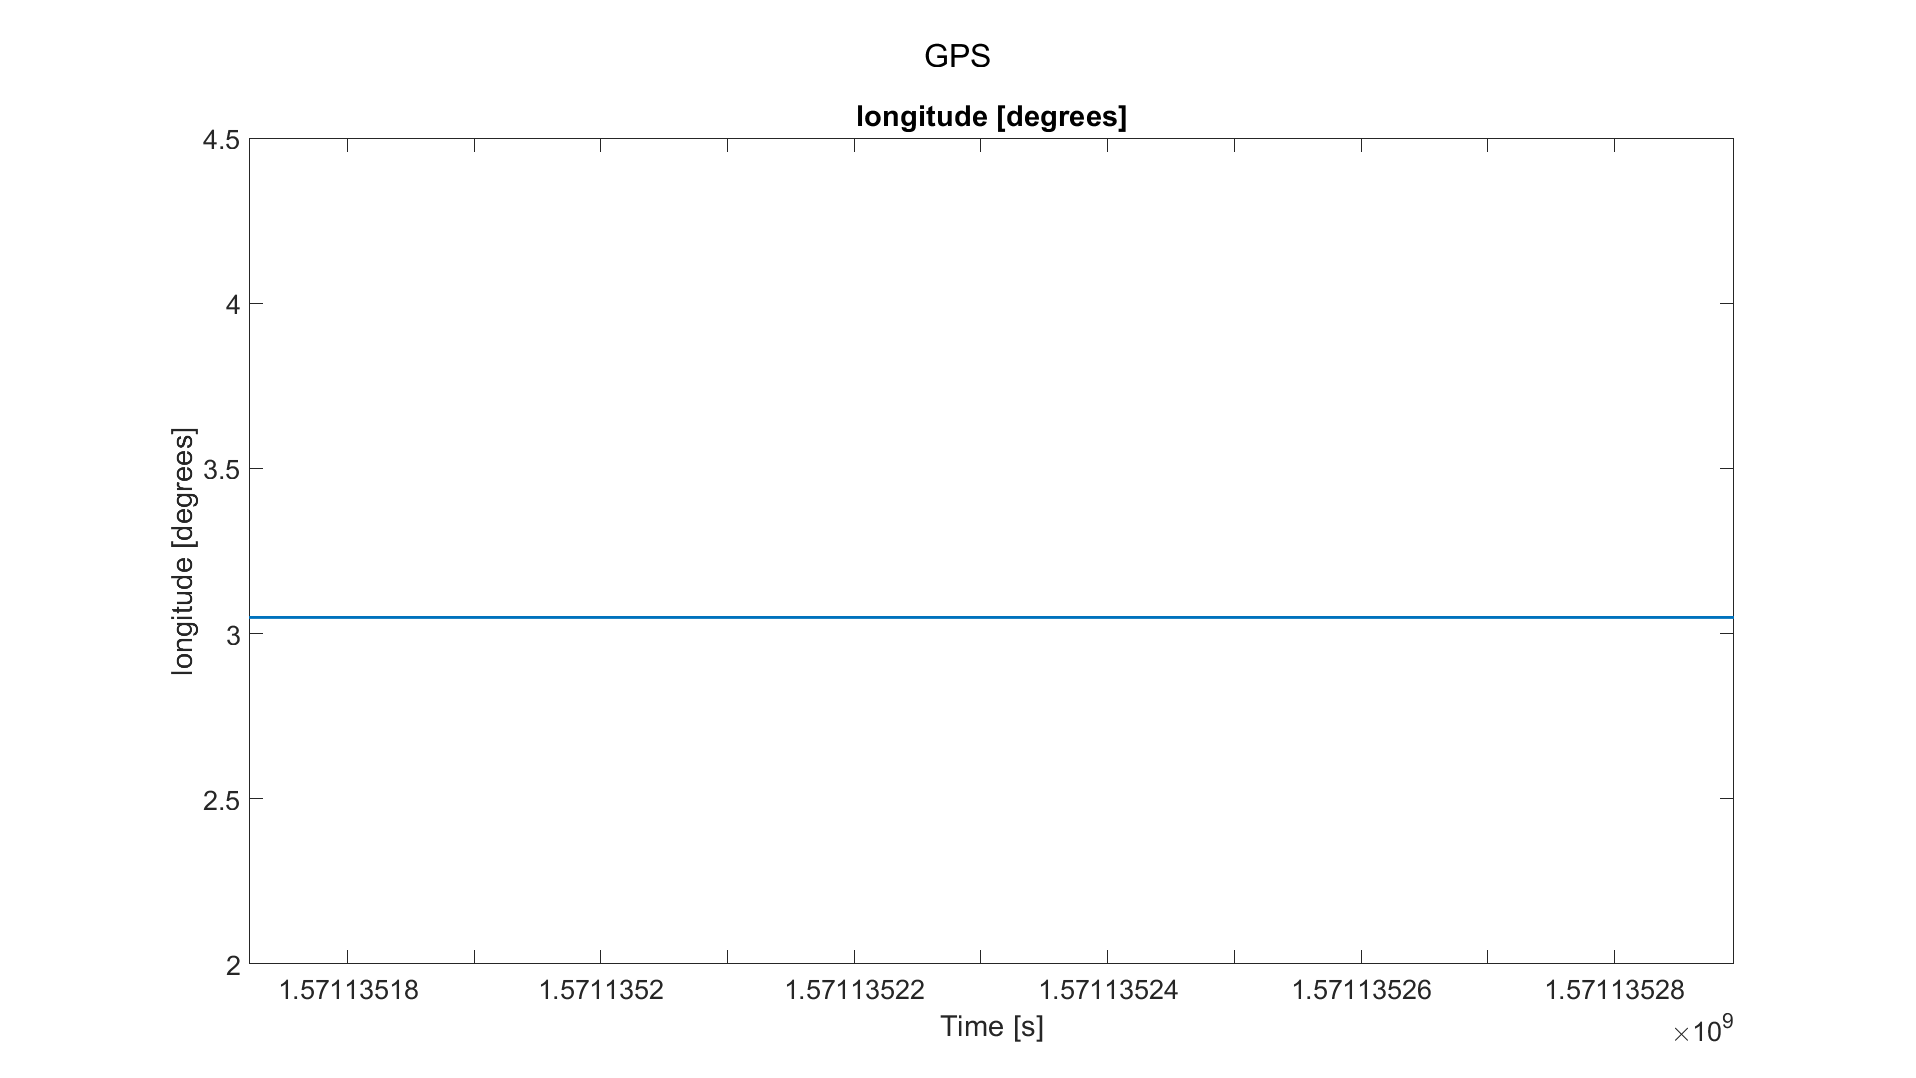

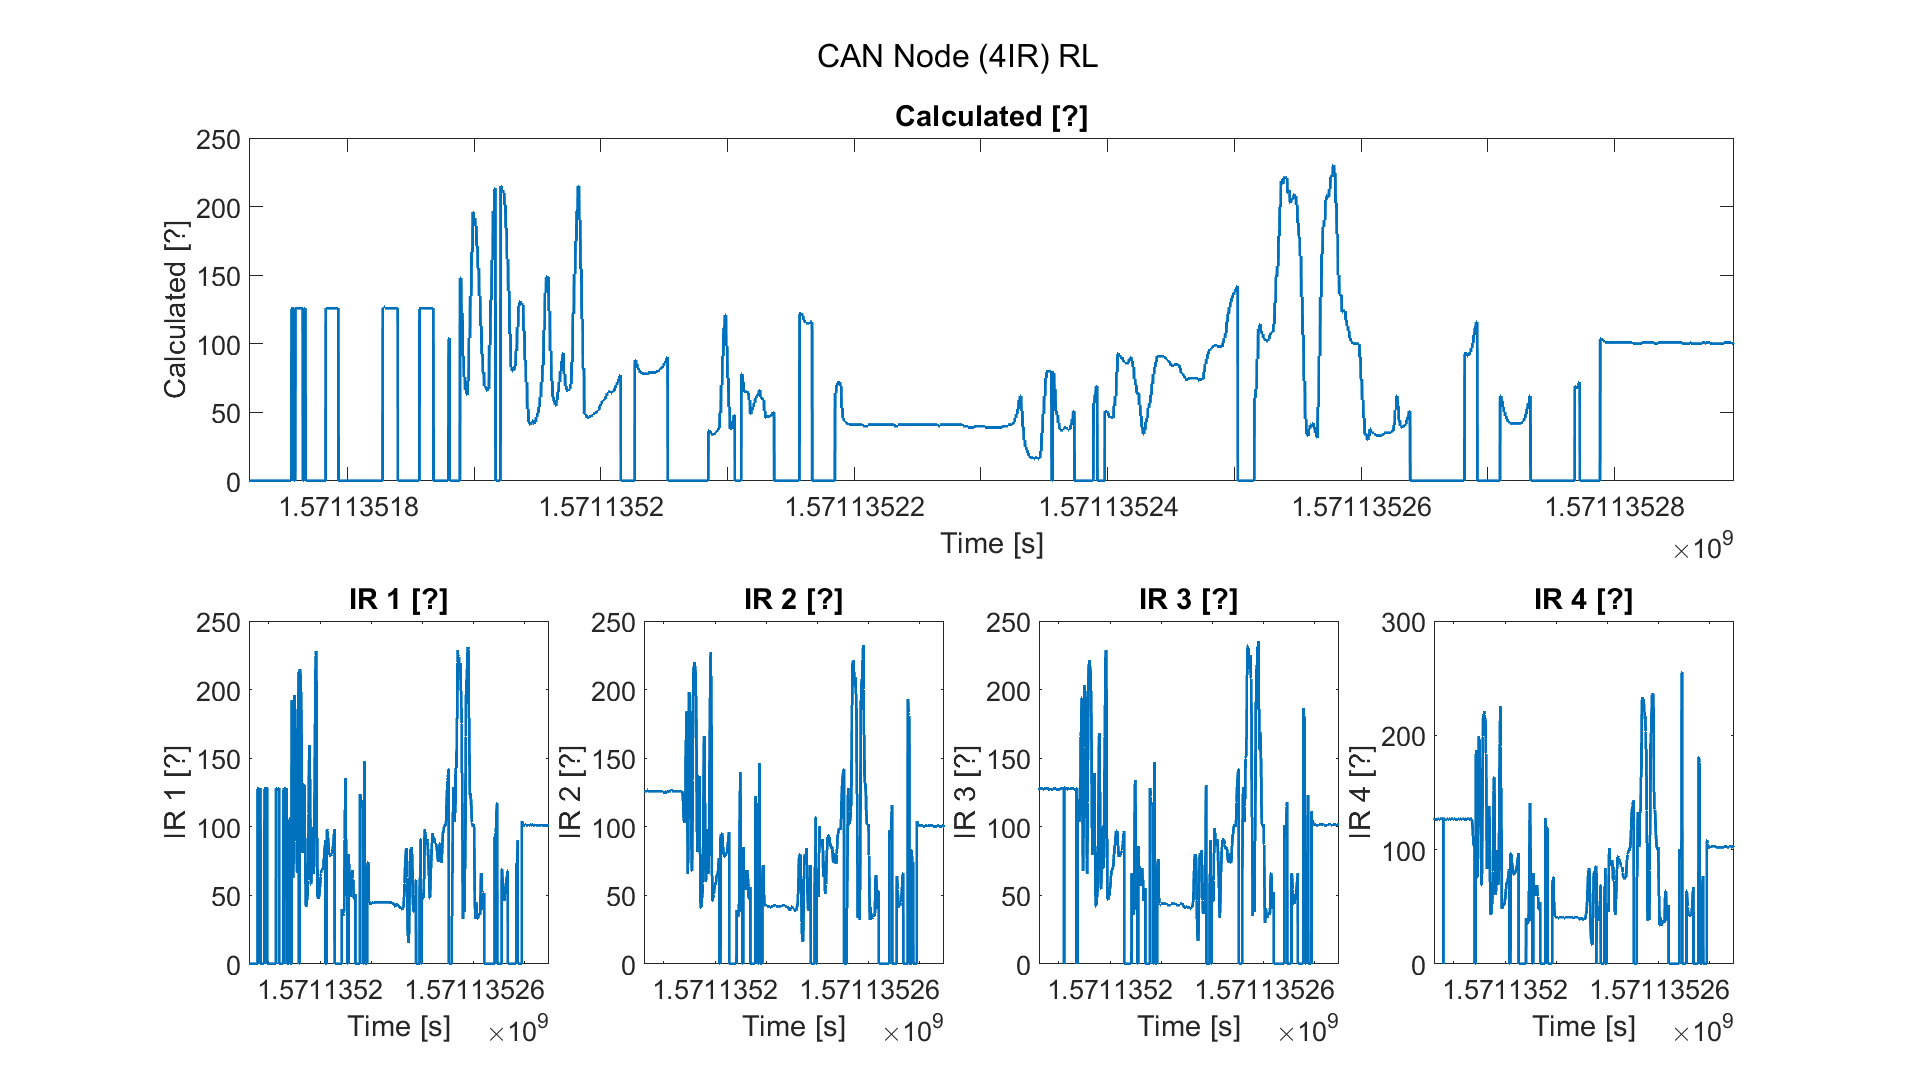

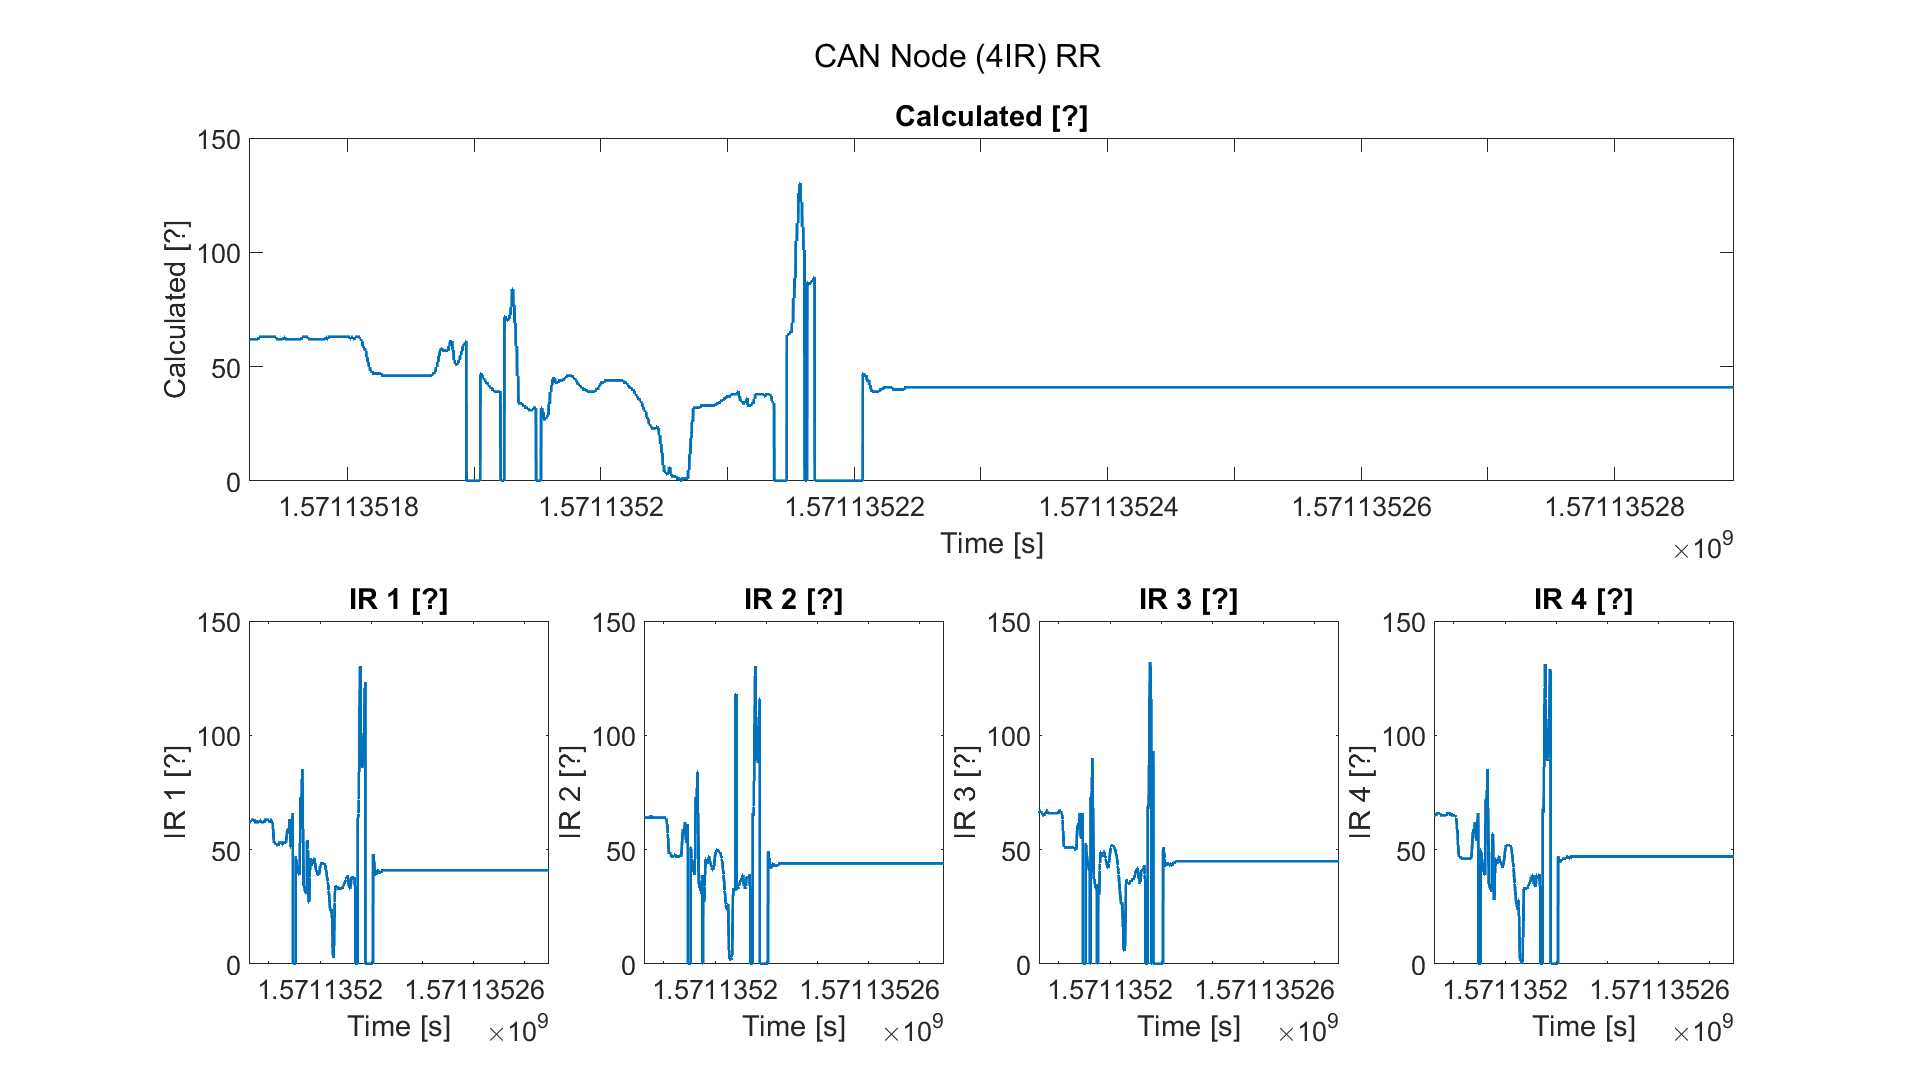

close all;
 
m.plot_all();

## Loop and add live datasets

time = (1:size( m.instruments(1, 2).data(1,6).values,2))*0.020 + m.start_time;

plotty("gz vs turn"

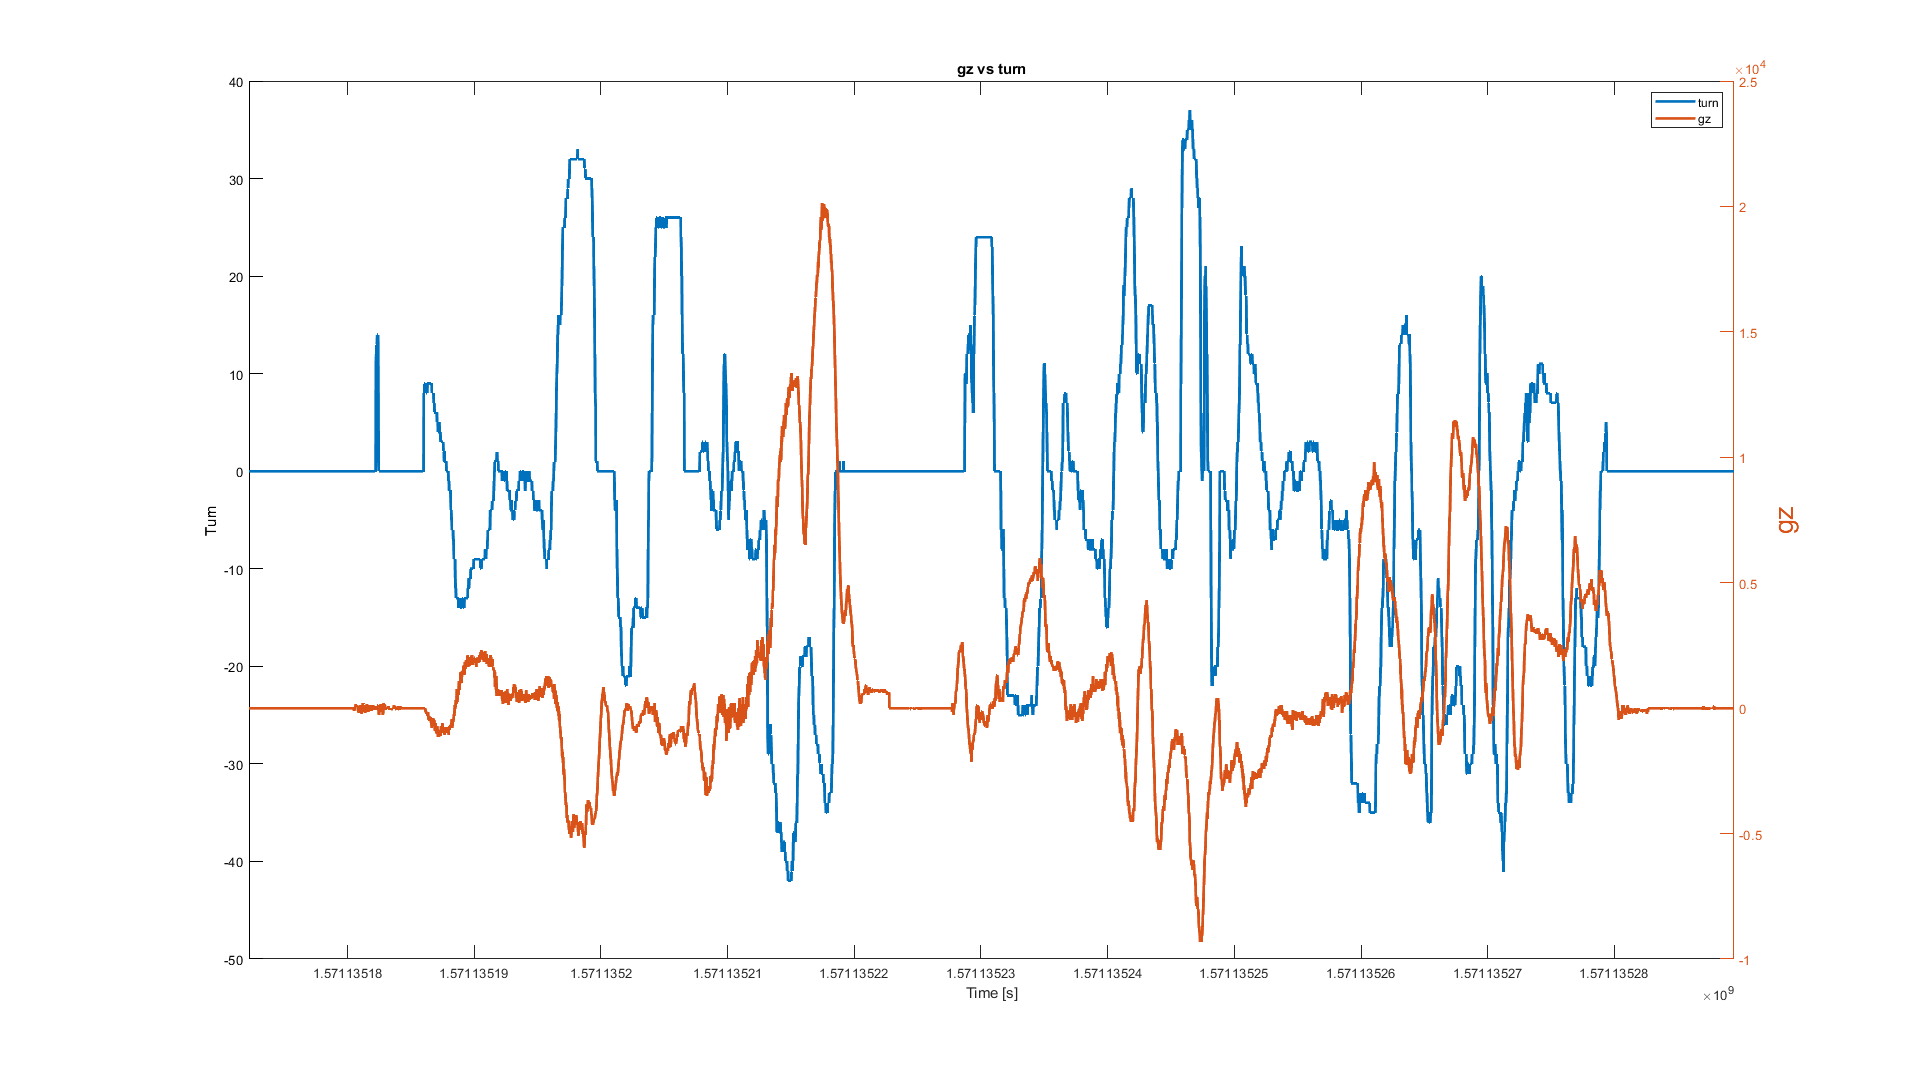

 
time = (1:size(m.instruments(1,2).data(1,6).values,2))*0.02 + m.start_time;
figure();
fontsize = 20;
set(gca,'fontsize',fontsize) % set fontsize of the plot to 20
set(gcf, 'Position', get(0,'Screensize')); % automatic full screen
set(0, 'DefaultAxesFontSize', fontsize);
plot(time,m.instruments(1,1).data(1,2).values,'LineWidth',2)
ylabel("Turn",'fontsize',fontsize);
ax1 = gca;
yyaxis right
plot(time, m.instruments(1,2).data(1,6).values,'LineWidth',2)
xlabel('Time [s]','fontsize',fontsize);
ylabel("gz",'fontsize',fontsize);
xlim(([min(time) (max(time))]));
title("gz vs turn" ,'fontsize',fontsize);
legend(["turn","gz"]);